# PRÁCTICA 4: Clasificadores

## Objetivos

En esta práctica avanzaremos en el uso de cuatro clasificadores supervisados (KNN, Naive Bayes, Arboles de Decisión y SVM) sobre distintos conjuntos de datos Iris y Wine. Cada ejercicio incluye:

- Preprocesamiento de datos

- Reducción de dimensionalidad PCA y visualización en 2D/3D

- Búsqueda e interpretación de hiperparámetros

- Análisis de resultados

## Introducción

### Tipos de Clasificadores para Reconocimiento de Patrones

El reconocimiento de patrones es una disciplina fundamental en  inteligencia artificial y aprendizaje automático, cuyo objetivo es identificar regularidades o estructuras en datos para asignarles categorías. Los clasificadores son algoritmos que implementan esta tarea, y su elección depende de factores como la naturaleza de los datos, la complejidad del problema y la necesidad de interpretabilidad. A continuación, se describen los principales tipos de clasificadores y sus características.

#### Clasificadores No Lineales

Cuando los datos presentan relaciones complejas, se emplean modelos no lineales. Los  árboles de decisión son un ejemplo: dividen recursivamente el espacio de características mediante reglas jerárquicas, lo que los hace interpretables pero propensos al sobreajuste. Otro enfoque es el algoritmo k-vecinos más cercanos (kNN), que clasifica instancias según la mayoría de clases entre sus vecinos más cercanos. Aunque es flexible y no requiere entrenamiento explícito, su costo computacional crece con el tamaño de los datos. Estos métodos son útiles en reconocimiento de escritura manual o sistemas de recomendación basados en similitud.

#### Clasificadores Probabilísticos

Basados en teoría de probabilidad, estos modelos estiman distribuciones para predecir clases. El clasificador Naive Bayes es el más conocido: asume independencia entre características y aplica el teorema de Bayes para calcular probabilidades. Aunque simplista, es eficaz en datos categóricos o textuales, como en análisis de sentimientos o detección de spam. Las redes Bayesianas, por otro lado, modelan dependencias entre variables, ofreciendo mayor flexibilidad a costa de complejidad.

#### Máquina de Soporte Vectorial (SVM)

Las SVM buscan hiperplanos óptimos para separar clases, incluso en espacios de alta dimensión. En su versión lineal, maximizan el margen entre clases, mientras que con kernels transforman los datos a espacios donde la separación no lineal es posible. Son eficaces en reconocimiento facial o clasificación de imágenes médicas, pero requieren ajuste de parámetros y normalización de datos.

#### Redes Neuronales

Estos modelos, inspirados en el cerebro humano, destacan por su capacidad para aprender patrones complejos. Los perceptrones multicapa (MLP) son redes *feed-forward* con capas ocultas no lineales, mientras que las redes convolucionales (CNN) se especializan en datos grid-like (como imágenes). Las redes recurrentes (RNN) manejan secuencias (texto, series temporales). Aunque son extremadamente poderosas (ej. en visión por computadora o traducción automática), requieren grandes volúmenes de datos, recursos computacionales y carecen de interpretabilidad.

## Desarrollo

### Ejercicio 1: Comparación de clasificadores KNN y DMIN utilizando el conjunto de datos de cáncer de mama.

El conjunto de datos de cáncer de mama es una clasificación binaria clásica, este set de datos busca determinar si una masa mamaria es un tumor benigno o maligno, a partir de las medidas obtenidas de imágenes digitalizadas de la aspiración con una aguja fina. Los valores representan las características de los núcleos celulares presentes en la imagen digital. La muestra contiene 569 ejemplos de resultados de las biopsias. Cada registro contiene 30 variables, las cuales corresponden a tres medidas (media, desviación estándar, peor caso) de diez características diferentes.

**1. Carga y limpieza de datos**

(a) Cargar el conjunto de datos *breast cancer wisconsin* dataset disponible para MATLAB y Python.

(b) Imprimir el nombre de las características y las etiquetas del conjunto de datos.

(c) Verificar y aplicar limpieza de datos (faltantes, outliers, caracteres inválidos, etc.).

(d) Contabilizar el número de muestras malignas y benignas.

**2. Preprocesamiento**

(a) Estandarización de características (*zscore()* si utilizas MATLAB y

*StandardScaler()* para Python).

(b) Separación en 70% entrenamiento y 30% prueba.

**3. Entrenamiento de modelos de KNN y DMIN**

(a) Entrenar modelo de KNN y probarlo con diferentes valores de k (1, 3, 5, 7, 9).

(b) Entrenar modelo de DMIN basado en distancia mínima a centroides.

**4. Reducción de dimensionalidad**

(a) Obtener la reducción de dimensionalidad del número de componentes para 95% de varianza.

(b) Generar gráfico de varianza acumulada con línea de referencia al 95%.

(c) Entrenar los modelos de KNN y DMIN con la nueva distribución de datos.

**5. Visualización de resultados**

(a) Mostrar las fronteras de decisión superponiendo datos de entrenamiento y prueba de todos los modelos entrenados con/sin reducción de dimensionalidad PCA.

(b) Mostrar distribución espacial de datos y posición de centroides en 2 y 3 dimensiones.

(c) Generar gráfico comparativo de rendimiento sobre las predicciones.

**6. Análisis de resultados**

(a) Comparación de exactitud entre de predicciones con/sin reducción de dimensionalidad PCA.

(b) Matrices de confusión para evaluar errores por clase.

### Ejercicio 2: Naive Bayes sobre el conjunto de datos *Wine*

**1. Carga y limpieza de Datos:**

(a) Utilizamos el dataset Wine que contiene 13 características químicas de vinos de 3 clases diferentes.

(b) Verificar y aplicar limpieza de datos (faltantes, outliers, caracteres inválidos, etc.).

(c) Dividir el conjunto de datos en 75% para entrenamiento y 25% de prueba.

**2. Preprocesamiento**

(a) Se implementaran dos tipos de modelos Naive Bayes por lo que el escalado de datos será diferente para cada uno.

(b) El modelo Bayesiano ingenuo gaussiano asume que los valores continuos asociados a cada característica se distribuyen según una distribución gaussiana.

(c) El modelo Bayes ingenuo multinomial asume que las características representan la frecuencia de términos, como el número de palabras, requiere datos no negativos.

**3. Entrenamiento de modelos de Bayesiano Ingenuo Gaussiano y Bayesiano Ingenuo Multinomial**

(a) Comentar y explicar la selección de hiperparámetros.

**4. Visualización de resultados**

(a) Mostrar las fronteras de decisión superponiendo datos de entrenamiento y prueba de todos los modelos entrenados.

(b) Mostrar distribución espacial de datos en 3 dimensiones.

(c) Generar gráfico comparativo de rendimiento sobre las predicciones.

**5. Análisis de resultados**

(a) Comparación de exactitud entre de predicciones de entrenamiento y prueba.

(b) Matrices de confusión para evaluar errores por clase.

## Ejercicio 3: Árboles de decisión sobre el conjunto de subespecies de flor iris

Esta es quizás la base de datos más conocida que se encuentra en el literatura de reconocimiento de patrones. El conjunto de datos contiene 3 clases de 50 instancias cada una, donde cada clase hace referencia a una subespecie de flor iris.

**1. Carga y limpieza de datos**

(a) Utilizamos el conjunto de la flor iris.

(b) Verificar que no haya valores faltantes y eliminar duplicados

**2. Preprocesamiento**

(a) Estandarizar las características escalando los datos.

(b) Dividir el conjuntos en 80% para entrenamiento y 20% de prueba.

**3. Entrenamiento del modelo de Árboles de decisión**

(a) Árbol de decisión con profundidad máxima 3.

(b) Evaluación con exactitud y matriz de confusión.

4. Visualización de resultados:

(a) Muestra la estructura del árbol con las reglas de decisión.

(b) Mostrar las fronteras de decisión superponiendo datos de entrenamiento y prueba.

(c) Mostrar distribución espacial de datos en 3 dimensiones.

## **Código**

clear; close all; clc;
format shortG;

### **Ejericio 1: **KNN y DMIN con el conjunto de datos de cáncer de mama

### Ejercicio 2: Naive Bayes sobre el conjunto de datos *Wine*

%% ===============================================
%% CARGA Y EXPLORACIÓN INICIAL DE DATOS
%% ===============================================
wine = readtable('./data/Wine.csv');
[n_samples, n_features] = size(wine);
fprintf('Dataset cargado: %d muestras, %d características\n', n_samples, n_features-1);

Dataset cargado: 178 muestras, 13 características


% Separar características y etiquetas
X = wine{:, 1:13};    % Características
y = wine{:, 14};      % Etiquetas

% Información básica del dataset
fprintf('Clases únicas: %s\n', mat2str(unique(y)'));

Clases únicas: [1 2 3]


fprintf('Distribución de clases:\n');

Distribución de clases:


for class = unique(y)'
    fprintf('  Clase %d: %d muestras (%.1f%%)\n', class, sum(y==class), 100*sum(y==class)/length(y));
end

  Clase 1: 59 muestras (33.1%)
  Clase 2: 71 muestras (39.9%)
  Clase 3: 48 muestras (27.0%)


%% ===============================================
%% LIMPIEZA DE DATOS
%% ===============================================
fprintf('\n=== LIMPIEZA DE DATOS ===\n');


=== LIMPIEZA DE DATOS ===


% 1. Detección y eliminación de valores faltantes
missingRows = any(ismissing(wine), 2);
if any(missingRows)
    fprintf('Eliminando %d filas con datos faltantes...\n', sum(missingRows));
    X(missingRows, :) = [];
    y(missingRows) = [];
else
    fprintf('No se encontraron valores faltantes.\n');
end

No se encontraron valores faltantes.


% 2. Detección y eliminación de outliers (método IQR)
fprintf('Detectando outliers usando método IQR...\n');

Detectando outliers usando método IQR...


original_size = size(X,1);
outlierRows = false(size(X, 1), 1);
for i = 1:size(X, 2)
    Q1 = quantile(X(:, i), 0.25);
    Q3 = quantile(X(:, i), 0.75);
    IQR = Q3 - Q1;
    lower_bound = Q1 - 1.5 * IQR;
    upper_bound = Q3 + 1.5 * IQR;
    outlierRows = outlierRows | (X(:, i) < lower_bound) | (X(:, i) > upper_bound);
end

if any(outlierRows)
    fprintf('Eliminando %d filas con outliers...\n', sum(outlierRows));
    X(outlierRows, :) = [];
    y(outlierRows) = [];
else
    fprintf('No se encontraron outliers significativos.\n');
end

Eliminando 16 filas con outliers...


% 3. Verificación de tipos de datos
if ~isnumeric(X) || ~isnumeric(y)
    error('Se encontraron valores no numéricos en X o en y después de la limpieza.');
end

fprintf('Datos después de limpieza: %d muestras (%.1f%% del original)\n', ...
        size(X,1), 100*size(X,1)/original_size);

Datos después de limpieza: 162 muestras (91.0% del original)


% Escalado Z-score
X_scaled = zscore(X);

% Reducción dimensional (PCA)
[~, score] = pca(X_scaled);
X_pca = score(:,1:3);

% División entrenamiento/prueba
rng(42);
cv = cvpartition(y, 'HoldOut', 0.25);
X_train = X_pca(cv.training,:);
y_train = y(cv.training);
X_test = X_pca(cv.test,:);
y_test = y(cv.test);

fprintf('Conjunto de entrenamiento: %d muestras\n', size(X_train, 1));

Conjunto de entrenamiento: 122 muestras


fprintf('Conjunto de prueba: %d muestras\n', size(X_test, 1));

Conjunto de prueba: 40 muestras


% Verificar distribución de clases en ambos conjuntos
fprintf('\nDistribución en entrenamiento:\n');


Distribución en entrenamiento:


for class = unique(y_train)'
    fprintf('  Clase %d: %d muestras (%.1f%%)\n', class, sum(y_train==class), 100*sum(y_train==class)/length(y_train));
end

  Clase 1: 43 muestras (35.2%)
  Clase 2: 46 muestras (37.7%)
  Clase 3: 33 muestras (27.0%)


fprintf('Distribución en prueba:\n');

Distribución en prueba:


for class = unique(y_test)'
    fprintf('  Clase %d: %d muestras (%.1f%%)\n', class, sum(y_test==class), 100*sum(y_test==class)/length(y_test));
end

  Clase 1: 15 muestras (37.5%)
  Clase 2: 15 muestras (37.5%)
  Clase 3: 10 muestras (25.0%)


%% ===============================================
%% PREPROCESAMIENTO PARA MULTINOMIAL NAIVE BAYES
%% ===============================================

% El Multinomial NB requiere valores no negativos (frecuencias)
% Método 1: Min-Max con rango global (considerando train y test)
fprintf('Calculando rango global para transformación Min-Max...\n');

Calculando rango global para transformación Min-Max...


X_combined = [X_train; X_test]; % Combinar para obtener rango global
min_vals_global = min(X_combined, [], 1);
max_vals_global = max(X_combined, [], 1);
range_vals_global = max_vals_global - min_vals_global;

% Evitar división por cero
range_vals_global(range_vals_global == 0) = 1;

% Normalización Min-Max usando rango global
X_train_norm = (X_train - min_vals_global) ./ range_vals_global;
X_test_norm = (X_test - min_vals_global) ./ range_vals_global;

% Verificar rangos después de normalización
fprintf('Rango en train después de Min-Max: [%.6f, %.6f]\n', min(X_train_norm(:)), max(X_train_norm(:)));

Rango en train después de Min-Max: [0.000000, 1.000000]


fprintf('Rango en test después de Min-Max: [%.6f, %.6f]\n', min(X_test_norm(:)), max(X_test_norm(:)));

Rango en test después de Min-Max: [0.000000, 0.963701]


% Método alternativo si aún hay problemas: Usar transformación de desplazamiento
if min(X_test_norm(:)) < 0 || min(X_train_norm(:)) < 0
    fprintf('Detectados valores negativos, aplicando método de desplazamiento...\n');
    
    % Encontrar el valor mínimo en todo el dataset
    min_value_all = min([X_train(:); X_test(:)]);
    
    % Desplazar todos los valores para que el mínimo sea 0
    X_train_shifted = X_train - min_value_all;
    X_test_shifted = X_test - min_value_all;
    
    % Aplicar Min-Max a los datos desplazados
    max_shifted = max([X_train_shifted(:); X_test_shifted(:)]);
    X_train_norm = X_train_shifted / max_shifted;
    X_test_norm = X_test_shifted / max_shifted;
    
    fprintf('Método de desplazamiento aplicado.\n');
    fprintf('Nuevo rango en train: [%.6f, %.6f]\n', min(X_train_norm(:)), max(X_train_norm(:)));
    fprintf('Nuevo rango en test: [%.6f, %.6f]\n', min(X_test_norm(:)), max(X_test_norm(:)));
end

% Escalar a rango de frecuencias enteras (multiplicar por 100 y redondear)
scaling_factor = 100;
X_train_multinom = round(X_train_norm * scaling_factor);
X_test_multinom = round(X_test_norm * scaling_factor);

% Asegurar que no hay valores negativos (forzar a 0 si los hay)
X_train_multinom = max(X_train_multinom, 0);
X_test_multinom = max(X_test_multinom, 0);

% Verificación final
if any(X_train_multinom(:) < 0) || any(X_test_multinom(:) < 0)
    error('Error: Aún hay valores negativos después de todas las transformaciones');
else
    fprintf('✓ Transformación exitosa: todos los valores son no negativos\n');
end

✓ Transformación exitosa: todos los valores son no negativos


fprintf('Datos preparados para Multinomial NB:\n');

Datos preparados para Multinomial NB:


fprintf('  Rango de valores en entrenamiento: [%d, %d]\n', ...
        min(X_train_multinom(:)), max(X_train_multinom(:)));

  Rango de valores en entrenamiento: [0, 100]


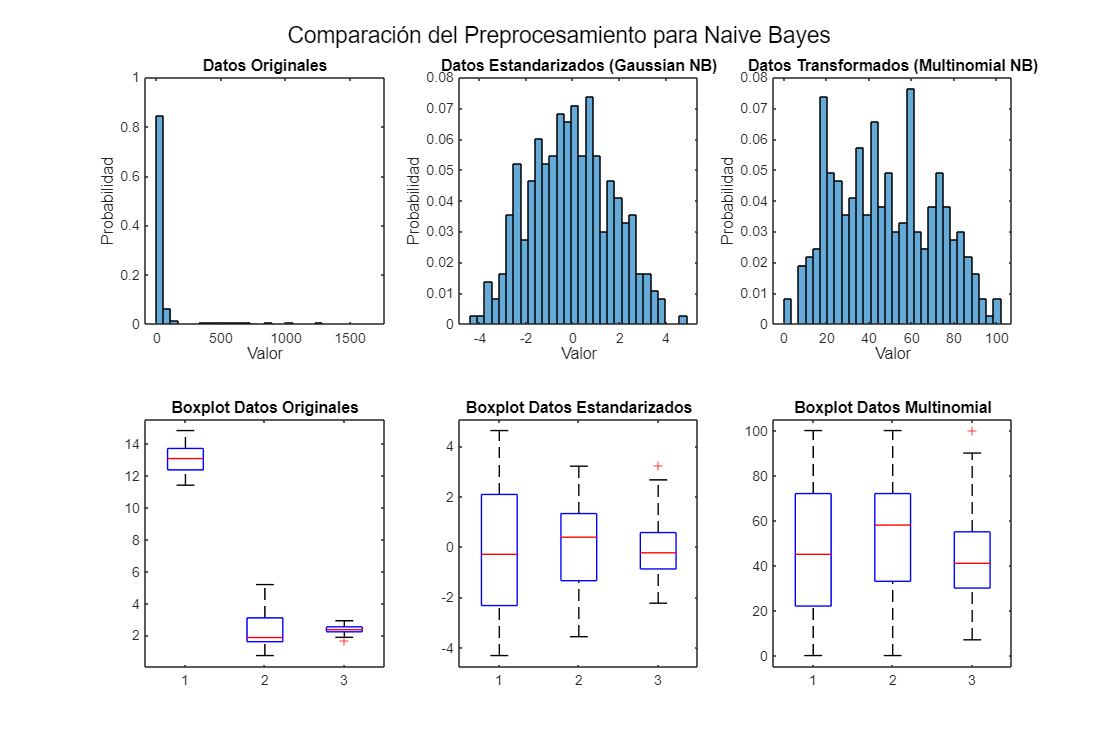

%% ===============================================
%% VISUALIZACIÓN DEL PREPROCESAMIENTO
%% ===============================================

% Comparación de distribuciones antes y después del preprocesamiento
figure('Position', [100, 100, 1200, 800]);

% Datos originales
subplot(2, 3, 1);
histogram(X(:), 30, 'Normalization', 'probability');
title('Datos Originales');
xlabel('Valor');
ylabel('Probabilidad');

% Datos estandarizados (Gaussian)
subplot(2, 3, 2);
histogram(X_train(:), 30, 'Normalization', 'probability');
title('Datos Estandarizados (Gaussian NB)');
xlabel('Valor');
ylabel('Probabilidad');

% Datos para Multinomial
subplot(2, 3, 3);
histogram(X_train_multinom(:), 30, 'Normalization', 'probability');
title('Datos Transformados (Multinomial NB)');
xlabel('Valor');
ylabel('Probabilidad');

% Boxplots de comparación
subplot(2, 3, 4);
boxplot(X(:, 1:3));
title('Boxplot Datos Originales');

subplot(2, 3, 5);
boxplot(X_train(:, 1:3));
title('Boxplot Datos Estandarizados');

subplot(2, 3, 6);
boxplot(X_train_multinom(:, 1:3));
title('Boxplot Datos Multinomial');

sgtitle('Comparación del Preprocesamiento para Naive Bayes');

%% ===============================================
%% ENTRENAMIENTO DE MODELOS BAYESIANOS INGENUOS
%% ===============================================
fprintf('\n=== ENTRENAMIENTO DE MODELOS NAIVE BAYES ===\n');


=== ENTRENAMIENTO DE MODELOS NAIVE BAYES ===


%% ENTRENAR MODELOS EN ESPACIO PCA
fprintf('\n=== ENTRENANDO MODELOS EN ESPACIO PCA ===\n');


=== ENTRENANDO MODELOS EN ESPACIO PCA ===


% Modelos Gaussianos en PCA
model_pca_classic = fitcnb(X_train(:,1:2), y_train, ...
    'DistributionNames', 'normal', 'Prior', 'uniform');

model_pca_empirical = fitcnb(X_train(:,1:2), y_train, ...
    'DistributionNames', 'normal', 'Prior', 'empirical');

model_pca_kernel = fitcnb(X_train(:,1:2), y_train, ...
    'DistributionNames', 'kernel', 'Prior', 'empirical');

% Para multinomial, usar los datos ya transformados
X_train_pca_multinom = X_train_multinom(:,1:2); % Primeras 2 componentes
X_test_pca_multinom = X_test_multinom(:,1:2);

model_pca_multinom_classic = fitcnb(X_train_pca_multinom, y_train, ...
    'DistributionNames', 'mn', 'Prior', 'uniform');

model_pca_multinom_empirical = fitcnb(X_train_pca_multinom, y_train, ...
    'DistributionNames', 'mn', 'Prior', 'empirical');

**ANÁLISIS DE HIPERPARÁMETROS Y CONFIGURACIONES**

GAUSSIAN NAIVE BAYES

- `DistributionNames = 'normal'`

- Asume que cada característica sigue distribución gaussiana

- Parámetros estimados: μ (media) y σ² (varianza) por clase y característica

- Apropiado cuando los datos son continuos y aproximadamente normales

- `DistributionNames = 'kernel'`

- Estimación no paramétrica usando densidad de kernel

- Más flexible, no asume forma específica de distribución

- `Kernel = 'normal': ` usa kernel gaussiano para suavizar

- `Prior`

- `'uniform': P(C) = 1/K `asume clases equiprobables

- `'empirical': P(C) = n_c/n `basado en frecuencias observadas

MULTINOMIAL NAIVE BAYES

- `DistributionNames = 'mn'`

- Asume distribución multinomial para cada característica

- Apropiado para datos de conteo/frecuencia

%% ===============================================
%% 4. COMPARACIÓN DE MODELOS ENTRENADOS
%% ===============================================
fprintf('\n=== INFORMACIÓN DE LOS MODELOS ===\n');


=== INFORMACIÓN DE LOS MODELOS ===


model_pca_classic

model_pca_classic =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2 3]
            ScoreTransform: 'none'
           NumObservations: 122
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {3×2 cell}


  Properties, Methods


model_pca_kernel

model_pca_kernel =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2 3]
            ScoreTransform: 'none'
           NumObservations: 122
         DistributionNames: {'kernel'  'kernel'}
    DistributionParameters: {3×2 cell}
                    Kernel: {'normal'  'normal'}
                   Support: {'unbounded'  'unbounded'}
                     Width: [3×2 double]
                        Mu: []
                     Sigma: []


  Properties, Methods


model_pca_empirical

model_pca_empirical =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2 3]
            ScoreTransform: 'none'
           NumObservations: 122
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {3×2 cell}


  Properties, Methods


model_pca_multinom_classic

model_pca_multinom_classic =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2 3]
            ScoreTransform: 'none'
           NumObservations: 122
         DistributionNames: 'mn'
    DistributionParameters: {3×2 cell}


  Properties, Methods


model_pca_multinom_empirical

model_pca_multinom_empirical =   ClassificationNaiveBayes
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2 3]
            ScoreTransform: 'none'
           NumObservations: 122
         DistributionNames: 'mn'
    DistributionParameters: {3×2 cell}


  Properties, Methods


**4. Visualización de resultados**

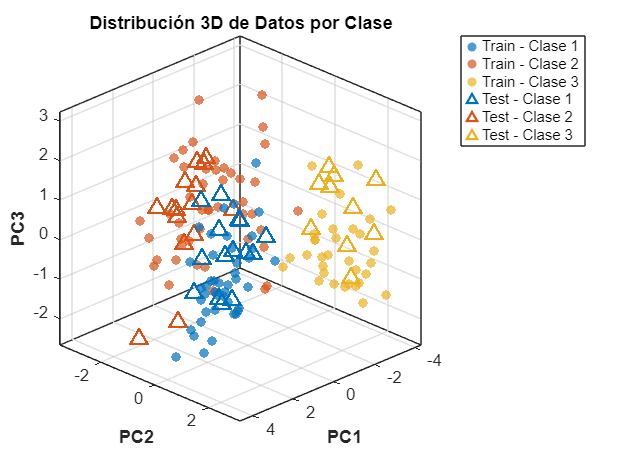

%% ===============================================
%% DISTRIBUCION DE CARACTERISTICAS
%% ===============================================
figure
hold on
colors = lines(3);  % Paleta de colores para 3 clases

% Graficar puntos de entrenamiento
for class = 1:3
    idx = y_train == class;
    scatter3(X_train(idx,1), X_train(idx,2), X_train(idx,3), ...
        40, colors(class,:), 'filled', 'MarkerFaceAlpha', 0.7, ...
        'DisplayName', ['Train - Clase ' num2str(class)]);
end

% Graficar puntos de prueba
for class = 1:3
    idx = y_test == class;
    scatter3(X_test(idx,1), X_test(idx,2), X_test(idx,3), ...
        100, colors(class,:), '^', 'LineWidth', 1.5, ...
        'DisplayName', ['Test - Clase ' num2str(class)]);
end

% Etiquetas y mejoras
xlabel('PC1', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('PC2', 'FontSize', 12, 'FontWeight', 'bold')
zlabel('PC3', 'FontSize', 12, 'FontWeight', 'bold')
title('Distribución 3D de Datos por Clase', 'FontSize', 14, 'FontWeight', 'bold')
grid on
box on
view(135, 25)
legend('Location', 'bestoutside')
set(gca, 'FontSize', 11)
axis tight

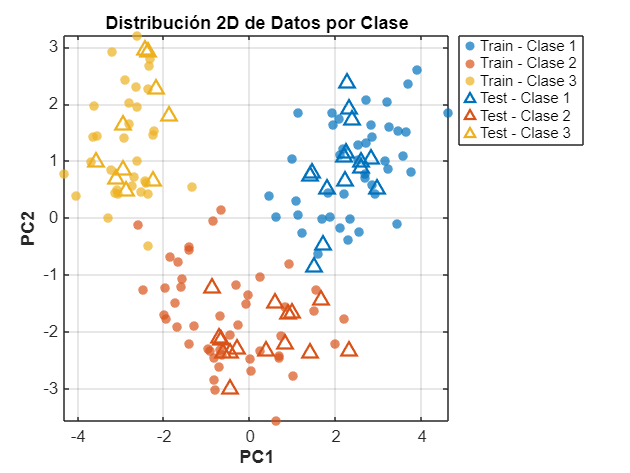

figure
hold on
colors = lines(3);  % Paleta de colores para 3 clases

% Graficar puntos de entrenamiento
for class = 1:3
    idx = y_train == class;
    scatter(X_train(idx,1), X_train(idx,2), ...
        40, colors(class,:), 'filled', 'MarkerFaceAlpha', 0.7, ...
        'DisplayName', ['Train - Clase ' num2str(class)]);
end

% Graficar puntos de prueba
for class = 1:3
    idx = y_test == class;
    scatter(X_test(idx,1), X_test(idx,2), ...
        80, colors(class,:), '^', 'LineWidth', 1.5, ...
        'DisplayName', ['Test - Clase ' num2str(class)]);
end

% Etiquetas y mejoras
xlabel('PC1', 'FontSize', 12, 'FontWeight', 'bold')
ylabel('PC2', 'FontSize', 12, 'FontWeight', 'bold')
title('Distribución 2D de Datos por Clase', 'FontSize', 14, 'FontWeight', 'bold')
grid on
box on
legend('Location', 'bestoutside')
set(gca, 'FontSize', 11)
axis tight

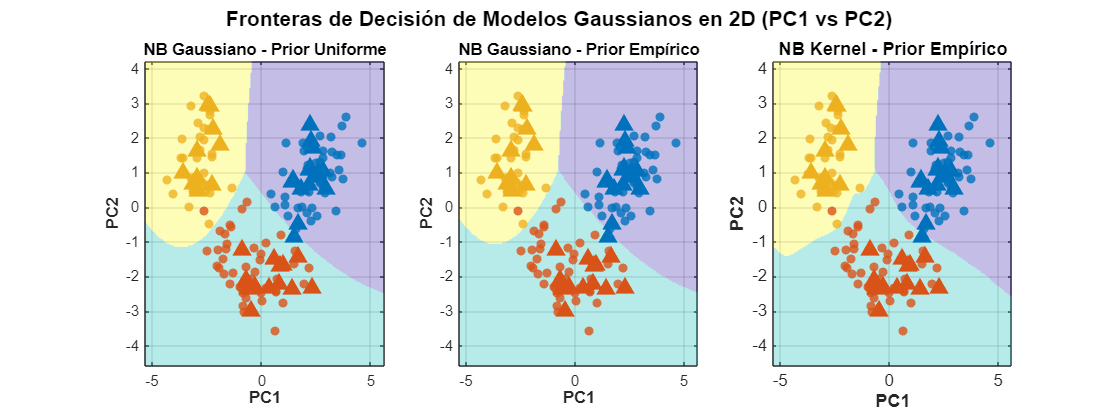

%% ===============================================
%% FRONTERAS DE DECISION
%% ===============================================

models = { ...
    model_pca_classic, ...
    model_pca_empirical, ...
    model_pca_kernel, ...
    model_pca_multinom_classic, ...
    model_pca_multinom_empirical ...
};

modelNames = { ...
    'NB Gaussiano - Prior Uniforme', ...
    'NB Gaussiano - Prior Empírico', ...
    'NB Kernel - Prior Empírico', ...
    'NB Multinomial - Prior Uniforme', ...
    'NB Multinomial - Prior Empírico' ...
};

% Preparar el rango global para PC1 y PC2
allX = [X_train(:,1:2); X_test(:,1:2)];
xMin = min(allX(:,1)) - 1;
xMax = max(allX(:,1)) + 1;
yMin = min(allX(:,2)) - 1;
yMax = max(allX(:,2)) + 1;

[xGrid, yGrid] = meshgrid(...
    linspace(xMin, xMax, 200), ...
    linspace(yMin, yMax, 200) ...
);
gridPoints = [xGrid(:), yGrid(:)];

% Colores para tres clases (1, 2 y 3)
classColors = lines(3);

% Crear figura con 1 fila y 3 columnas
figure('Units','normalized','Position',[0.1 0.1 0.85 0.5])

for i = 1:3
    mdl = models{i};
    ax = subplot(1, 3, i);
    hold(ax, 'on')

    % Predecir clases sobre la malla
    gridLabels = predict(mdl, gridPoints);
    gridLabels = reshape(gridLabels, size(xGrid));
    
    % Dibujar las regiones de decisión
    contourf(ax, xGrid, yGrid, gridLabels, 'LineColor', 'none')
    colormap(ax, parula(3))
    % Hacer el fondo semitransparente
    hContour = ax.Children(1);
    hContour.FaceAlpha = 0.3;

    % Graficar puntos de entrenamiento (círculos)
    for cls = 1:3
        idx_train = (y_train == cls);
        scatter( ...
            ax, ...
            X_train(idx_train,1), ...
            X_train(idx_train,2), ...
            36, classColors(cls,:), 'o', ...
            'filled', 'MarkerFaceAlpha', 0.8, ...
            'DisplayName', ['Train – Clase ' num2str(cls)] ...
        );
    end

    % Graficar puntos de prueba (triángulos con FaceColor igual a classColors)
    for cls = 1:3
        idx_test = (y_test == cls);
        scatter( ...
            ax, ...
            X_test(idx_test,1), ...
            X_test(idx_test,2), ...
            80, classColors(cls,:), '^', ...
            'filled', 'MarkerFaceAlpha', 1, ...
            'MarkerEdgeColor', classColors(cls,:), ...
            'LineWidth', 1.5, ...
            'DisplayName', ['Test – Clase ' num2str(cls)] ...
        );
    end

    xlabel(ax, 'PC1', 'FontSize', 11, 'FontWeight', 'bold')
    ylabel(ax, 'PC2', 'FontSize', 11, 'FontWeight', 'bold')
    title(ax, modelNames{i}, 'FontSize', 12, 'FontWeight', 'bold')
    axis(ax, [xMin xMax yMin yMax])
    grid(ax, 'on')
    box(ax, 'on')
    set(ax, 'FontSize', 10)
    hold(ax, 'off')
end
sgtitle('Fronteras de Decisión de Modelos Gaussianos en 2D (PC1 vs PC2)', ...
        'FontSize', 14, 'FontWeight', 'bold')
grid on
box on
set(gca, 'FontSize', 11)
axis tight

%% ===============================================
%% GRAFICO COMPARATIVO
%% ===============================================

% Modelos gaussianos
models = {model_pca_classic, model_pca_empirical, model_pca_kernel};
titles = {'Gaussiano Clásico (Prior Uniforme)', 'Gaussiano Empírico', 'Kernel'};
train_data = {X_train(:,1:2), X_train(:,1:2), X_train(:,1:2)};
test_data = {X_test(:,1:2), X_test(:,1:2), X_test(:,1:2)};

accuracies_train = zeros(1, 3);
conf_matrices_train = cell(1, 3);

accuracies_test = zeros(1, 3);
conf_matrices_test = cell(1, 3);

for i = 1:3
    y_pred_train = predict(models{i}, train_data{i});
    accuracies_train(i) = mean(y_train == y_pred_train) * 100;
    conf_matrices_train{i} = confusionmat(y_train, y_pred_train);
    
    fprintf('%s: %.1f%% accuracy\n', titles{i}, accuracies_train(i));
end

Gaussiano Clásico (Prior Uniforme): 99.2% accuracy
Gaussiano Empírico: 99.2% accuracy
Kernel: 99.2% accuracy




for i = 1:3
    y_pred_test = predict(models{i}, test_data{i});
    accuracies_test(i) = mean(y_test == y_pred_test) * 100;
    conf_matrices_test{i} = confusionmat(y_test, y_pred_test);
    
    fprintf('%s: %.1f%% accuracy\n', titles{i}, accuracies_test(i));
end

Gaussiano Clásico (Prior Uniforme): 97.5% accuracy
Gaussiano Empírico: 97.5% accuracy
Kernel: 97.5% accuracy


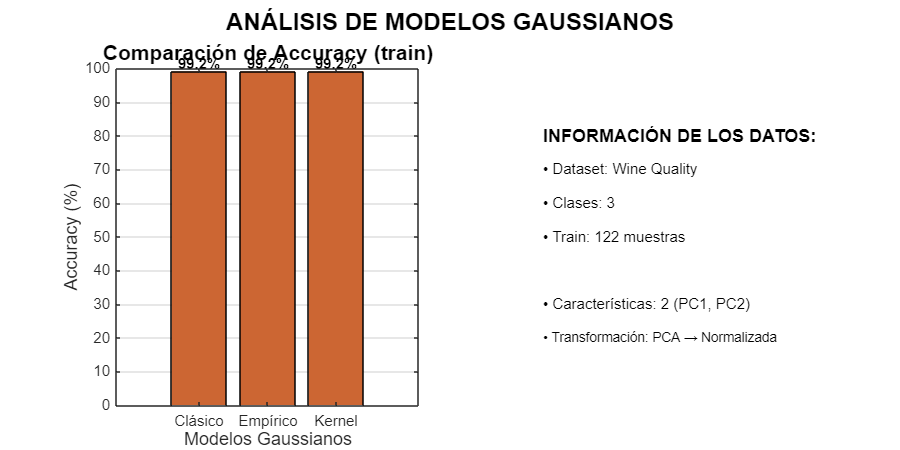

% Gráfico comparativo
figure('Position', [200, 200, 800, 400]);

subplot(1, 2, 1);
bar(accuracies_train, 'FaceColor', [0.8 0.4 0.2]);
title('Comparación de Accuracy (train)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Accuracy (%)', 'FontSize', 12);
xlabel('Modelos Gaussianos', 'FontSize', 12);
set(gca, 'XTickLabel', {'Clásico', 'Empírico', 'Kernel'});
ylim([0, 100]);
grid on;

% Añadir valores encima de las barras
for i = 1:3
    text(i, accuracies_train(i) + 2, sprintf('%.1f%%', accuracies_train(i)), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% Mostrar información adicional
subplot(1, 2, 2);
text(0.1, 0.8, 'INFORMACIÓN DE LOS DATOS:', 'FontSize', 12, 'FontWeight', 'bold');
text(0.1, 0.7, sprintf('• Dataset: Wine Quality'), 'FontSize', 10);
text(0.1, 0.6, sprintf('• Clases: %d', length(unique(y_train))), 'FontSize', 10);
text(0.1, 0.5, sprintf('• Train: %d muestras', length(y_train)), 'FontSize', 10);
text(0.1, 0.3, sprintf('• Características: 2 (PC1, PC2)'), 'FontSize', 10);
text(0.1, 0.2, sprintf('• Transformación: PCA → Normalizada'), 'FontSize', 9);
axis off;

sgtitle('ANÁLISIS DE MODELOS GAUSSIANOS', 'FontSize', 16, 'FontWeight', 'bold');

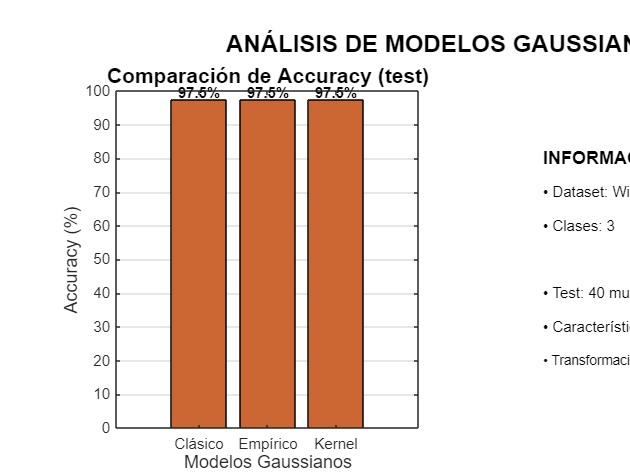

figure('Position', [200, 200, 800, 400]);

subplot(1, 2, 1);
bar(accuracies_test, 'FaceColor', [0.8 0.4 0.2]);
title('Comparación de Accuracy (test)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Accuracy (%)', 'FontSize', 12);
xlabel('Modelos Gaussianos', 'FontSize', 12);
set(gca, 'XTickLabel', {'Clásico', 'Empírico', 'Kernel'});
ylim([0, 100]);
grid on;

% Añadir valores encima de las barras
for i = 1:3
    text(i, accuracies_test(i) + 2, sprintf('%.1f%%', accuracies_test(i)), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% Mostrar información adicional
subplot(1, 2, 2);
text(0.1, 0.8, 'INFORMACIÓN DE LOS DATOS:', 'FontSize', 12, 'FontWeight', 'bold');
text(0.1, 0.7, sprintf('• Dataset: Wine Quality'), 'FontSize', 10);
text(0.1, 0.6, sprintf('• Clases: %d', length(unique(y_train))), 'FontSize', 10);
text(0.1, 0.4, sprintf('• Test: %d muestras', length(y_test)), 'FontSize', 10);
text(0.1, 0.3, sprintf('• Características: 2 (PC1, PC2)'), 'FontSize', 10);
text(0.1, 0.2, sprintf('• Transformación: PCA → Normalizada'), 'FontSize', 9);
axis off;

sgtitle('ANÁLISIS DE MODELOS GAUSSIANOS', 'FontSize', 16, 'FontWeight', 'bold');

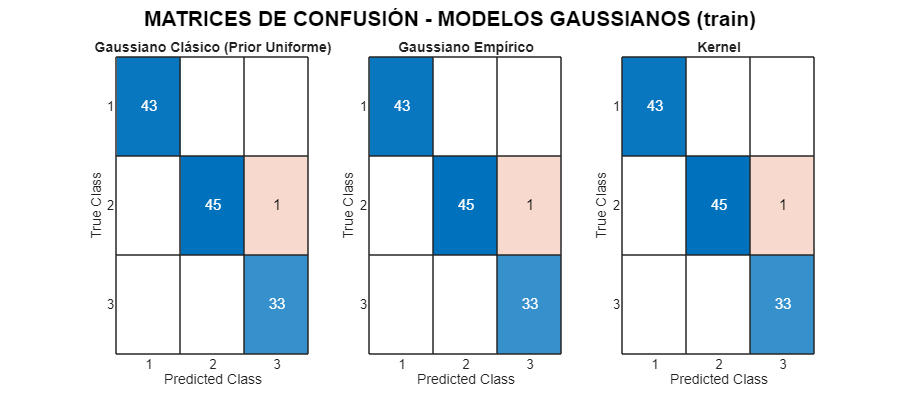

%% MATRICES DE CONFUSIÓN
figure('Position', [300, 300, 800, 350]);

for i = 1:3
    subplot(1, 3, i);
    y_pred_train = predict(models{i}, train_data{i});
    confusionchart(y_train, y_pred_train, 'Title', titles{i}, 'FontSize', 10);
end

sgtitle('MATRICES DE CONFUSIÓN - MODELOS GAUSSIANOS (train)', 'FontSize', 14, 'FontWeight', 'bold');

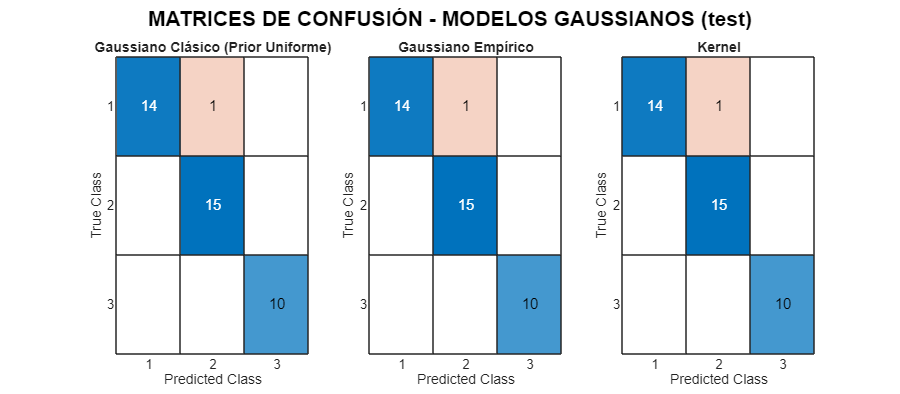

%% MATRICES DE CONFUSIÓN
figure('Position', [300, 300, 800, 350]);

for i = 1:3
    subplot(1, 3, i);
    y_pred_test = predict(models{i}, test_data{i});
    confusionchart(y_test, y_pred_test, 'Title', titles{i}, 'FontSize', 10);
end

sgtitle('MATRICES DE CONFUSIÓN - MODELOS GAUSSIANOS (test)', 'FontSize', 14, 'FontWeight', 'bold');

% Modelos multinomiales
models = {model_pca_multinom_classic, model_pca_multinom_empirical};
titles = {'Multinomial Clásico (Prior Uniforme)', 'Multinomial Empírico'};
train_data = {X_train_pca_multinom, X_train_pca_multinom};
test_data = {X_test_pca_multinom, X_test_pca_multinom};

accuracies_multinom_train = zeros(1, 2);
conf_matrices_train = cell(1, 2);

accuracies_multinom_test = zeros(1, 2);
conf_matrices_test = cell(1, 2);

for i = 1:2
    y_pred_train = predict(models{i}, train_data{i});
    accuracies_multinom_train(i) = mean(y_train == y_pred_train) * 100;
    conf_matrices_train{i} = confusionmat(y_train, y_pred_train);
    
    fprintf('%s: %.1f%% accuracy\n', titles{i}, accuracies_multinom_train(i));
end

Multinomial Clásico (Prior Uniforme): 79.5% accuracy
Multinomial Empírico: 79.5% accuracy



for i = 1:2
    y_pred_test = predict(models{i}, test_data{i});
    accuracies_multinom_test(i) = mean(y_test == y_pred_test) * 100;
    conf_matrices_test{i} = confusionmat(y_test, y_pred_test);
    
    fprintf('%s: %.1f%% accuracy\n', titles{i}, accuracies_multinom_test(i));
end

Multinomial Clásico (Prior Uniforme): 90.0% accuracy
Multinomial Empírico: 90.0% accuracy


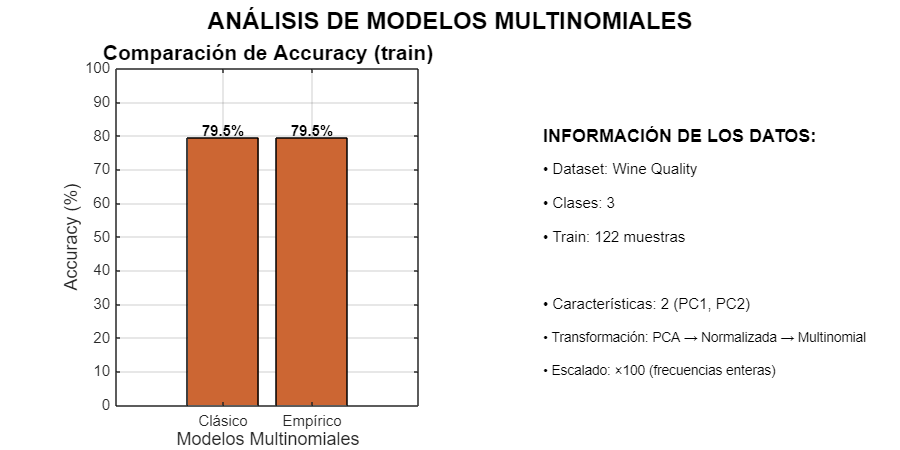

% Gráfico comparativo
figure('Position', [200, 200, 800, 400]);

subplot(1, 2, 1);
bar(accuracies_multinom_train, 'FaceColor', [0.8 0.4 0.2]);
title('Comparación de Accuracy (train)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Accuracy (%)', 'FontSize', 12);
xlabel('Modelos Multinomiales', 'FontSize', 12);
set(gca, 'XTickLabel', {'Clásico', 'Empírico'});
ylim([0, 100]);
grid on;

% Añadir valores encima de las barras
for i = 1:2
    text(i, accuracies_multinom_train(i) + 2, sprintf('%.1f%%', accuracies_multinom_train(i)), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% Mostrar información adicional
subplot(1, 2, 2);
text(0.1, 0.8, 'INFORMACIÓN DE LOS DATOS:', 'FontSize', 12, 'FontWeight', 'bold');
text(0.1, 0.7, sprintf('• Dataset: Wine Quality'), 'FontSize', 10);
text(0.1, 0.6, sprintf('• Clases: %d', length(unique(y_train))), 'FontSize', 10);
text(0.1, 0.5, sprintf('• Train: %d muestras', length(y_train)), 'FontSize', 10);
text(0.1, 0.3, sprintf('• Características: 2 (PC1, PC2)'), 'FontSize', 10);
text(0.1, 0.2, sprintf('• Transformación: PCA → Normalizada → Multinomial'), 'FontSize', 9);
text(0.1, 0.1, sprintf('• Escalado: ×%d (frecuencias enteras)', scaling_factor), 'FontSize', 9);
axis off;

sgtitle('ANÁLISIS DE MODELOS MULTINOMIALES', 'FontSize', 16, 'FontWeight', 'bold');

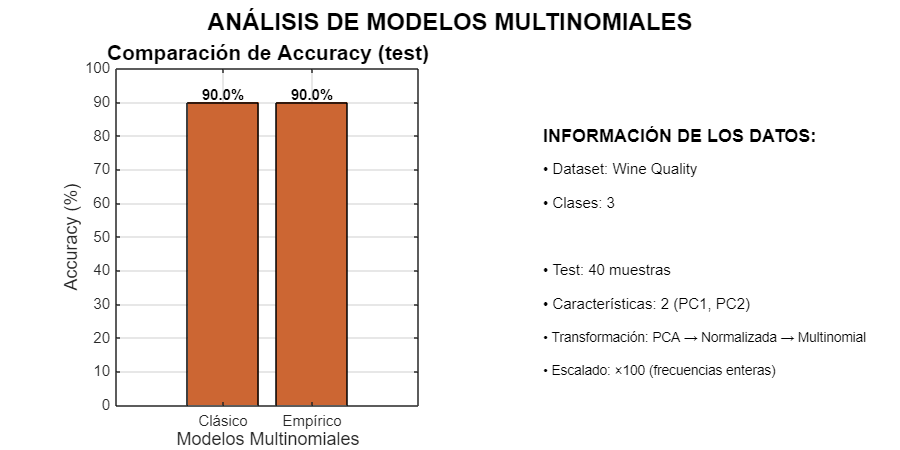

%%%

figure('Position', [200, 200, 800, 400]);

subplot(1, 2, 1);
bar(accuracies_multinom_test, 'FaceColor', [0.8 0.4 0.2]);
title('Comparación de Accuracy (test)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Accuracy (%)', 'FontSize', 12);
xlabel('Modelos Multinomiales', 'FontSize', 12);
set(gca, 'XTickLabel', {'Clásico', 'Empírico'});
ylim([0, 100]);
grid on;

% Añadir valores encima de las barras
for i = 1:2
    text(i, accuracies_multinom_test(i) + 2, sprintf('%.1f%%', accuracies_multinom_test(i)), ...
         'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

% Mostrar información adicional
subplot(1, 2, 2);
text(0.1, 0.8, 'INFORMACIÓN DE LOS DATOS:', 'FontSize', 12, 'FontWeight', 'bold');
text(0.1, 0.7, sprintf('• Dataset: Wine Quality'), 'FontSize', 10);
text(0.1, 0.6, sprintf('• Clases: %d', length(unique(y_train))), 'FontSize', 10);
text(0.1, 0.4, sprintf('• Test: %d muestras', length(y_test)), 'FontSize', 10);
text(0.1, 0.3, sprintf('• Características: 2 (PC1, PC2)'), 'FontSize', 10);
text(0.1, 0.2, sprintf('• Transformación: PCA → Normalizada → Multinomial'), 'FontSize', 9);
text(0.1, 0.1, sprintf('• Escalado: ×%d (frecuencias enteras)', scaling_factor), 'FontSize', 9);
axis off;

sgtitle('ANÁLISIS DE MODELOS MULTINOMIALES', 'FontSize', 16, 'FontWeight', 'bold');

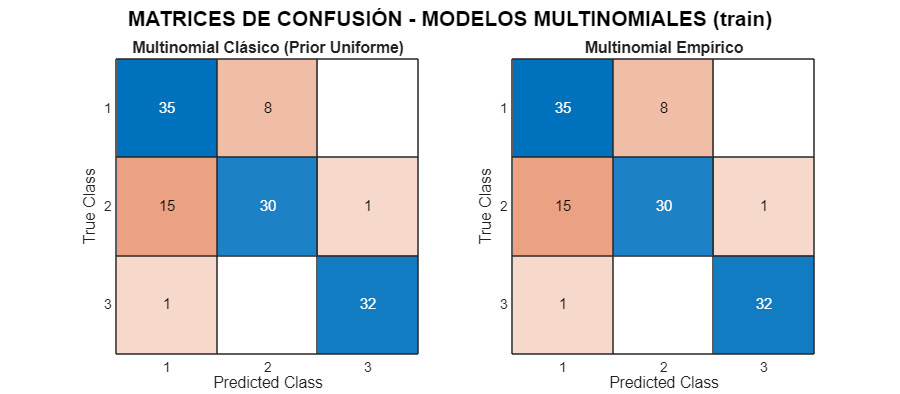

%% MATRICES DE CONFUSIÓN
figure('Position', [300, 300, 800, 350]);

for i = 1:2
    subplot(1, 2, i);
    y_pred_train = predict(models{i}, train_data{i});
    confusionchart(y_train, y_pred_train, 'Title', titles{i}, 'FontSize', 10);
end

sgtitle('MATRICES DE CONFUSIÓN - MODELOS MULTINOMIALES (train)', 'FontSize', 14, 'FontWeight', 'bold');

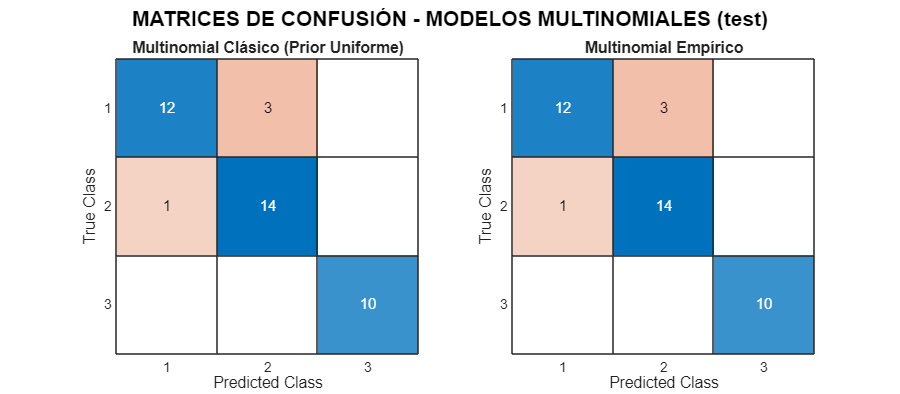


figure('Position', [300, 300, 800, 350]);

for i = 1:2
    subplot(1, 2, i);
    y_pred_test = predict(models{i}, test_data{i});
    confusionchart(y_test, y_pred_test, 'Title', titles{i}, 'FontSize', 10);
end

sgtitle('MATRICES DE CONFUSIÓN - MODELOS MULTINOMIALES (test)', 'FontSize', 14, 'FontWeight', 'bold');


%% RESUMEN
[best_acc, best_idx] = max(accuracies_test);
fprintf('Mejor modelo gaussiano: %s\n', titles{best_idx});

Mejor modelo gaussiano: Multinomial Clásico (Prior Uniforme)


fprintf('Mejor accuracy: %.1f%%\n', best_acc);

Mejor accuracy: 97.5%



[best_acc, best_idx] = max(accuracies_multinom_test);
fprintf('Mejor modelo multinomial: %s\n', titles{best_idx});

Mejor modelo multinomial: Multinomial Clásico (Prior Uniforme)


fprintf('Mejor accuracy: %.1f%%\n', best_acc);

Mejor accuracy: 90.0%


**5. Análisis de resultados**

En el análisis de modelos de clasificación aplicados al conjunto de datos clásico de vinos, se compararon distintas variantes del clasificador Naive Bayes: Gaussiano (con prior uniforme y empírico), Gaussiano con kernel, y Multinomial (también con prior uniforme y empírico). Los resultados obtenidos muestran un rendimiento notablemente alto para los modelos gaussianos, con una exactitud del 99.2 % en el conjunto de entrenamiento y del 97.5 % en el conjunto de prueba, sin diferencias entre las versiones clásica, empírica o con kernel, lo que sugiere una gran estabilidad y adecuación del supuesto de normalidad a este conjunto de datos. Por otro lado, el modelo Naive Bayes Multinomial mostró un comportamiento menos consistente: aunque obtuvo una exactitud más baja en el entrenamiento (79.5 %), logró un rendimiento aceptable en el conjunto de prueba con un 90.0 % de exactitud. Esta discrepancia podría deberse a que el modelo multinomial, más adecuado para datos discretos como texto o conteos, no se ajusta tan bien a las características continuas del conjunto de vinos. En conjunto, los resultados indican que el modelo Naive Bayes Gaussiano es el más apropiado para este caso, mostrando tanto alta precisión como buena generalización.

### Ejercicio 3: Árboles de decisión sobre el conjunto de subespecies de flor iris

## Conclusiones

## Referencias

- Tolstikhin, Ilya O., et al. *Mlp-mixer: An all-mlp architecture for vision. *Advances in neural information processing systems 34 (2021): 24261-24272.

- Wu, Baoyuan, et al. *Defenses in adversarial machine learning: A survey. *arXiv preprint arXiv:2312.08890 (2023).

- Liu, Xiao, et al. *Self-supervised learning: Generative or contrastive*. IEEE transactions on knowledge and data engineering 35.1 (2021): 857-876.

- Goodfellow, Ian. *Deep learning.* (2016).\

- Murphy, Kevin P. *Machine learning: a probabilistic perspective*. MIT press, 2012.

- Wolberg, W., Mangasarian, O., Street, N., Street, W. (1993). *Breast Cancer Wisconsin* *(Diagnostic)* [Dataset]. UCI Machine Learning Repository. [https://doi.org/10.24432/C5DW2B](https://doi.org/10.24432/C5DW2B)

- Cortez, P., Cerdeira, A., Almeida, F., Matos, T., Reis, J. (2009). *Wine Quality* [Dataset]. UCI Machine Learning Repository. [https://doi.org/10.24432/C56S3T](https://doi.org/10.24432/C56S3T)

- Fisher, R. (1936). *Iris* [Dataset]. UCI Machine Learning Repository. [https://doi.org/10.24432/C56C76](https://doi.org/10.24432/C56C76)